**Purpose**: Incorporate spike-timing-dependent plasticity (STDP learning) into any of your DynaSim spiking models.

"STDP_Isyn" can be incorporated into a Dynasim model as a connection mechanism between any two populations of neurons. 

This tutorial demonstrates how to use it in a simple toy model with two HH-type neurons (E1 and E2). 

The last plot that the script generates shows the synaptic weight increasing after each spike from E1 to E2.

The connection mechanism consists of AMPA and NMDA synapses with the "online implementation" of an STDP model with soft bounds described here: [http://www.scholarpedia.org/article/Spike-timing_dependent_plasticity#Online_implementation_of_STDP_models](http://www.scholarpedia.org/article/Spike-timing_dependent_plasticity#Online_implementation_of_STDP_models)

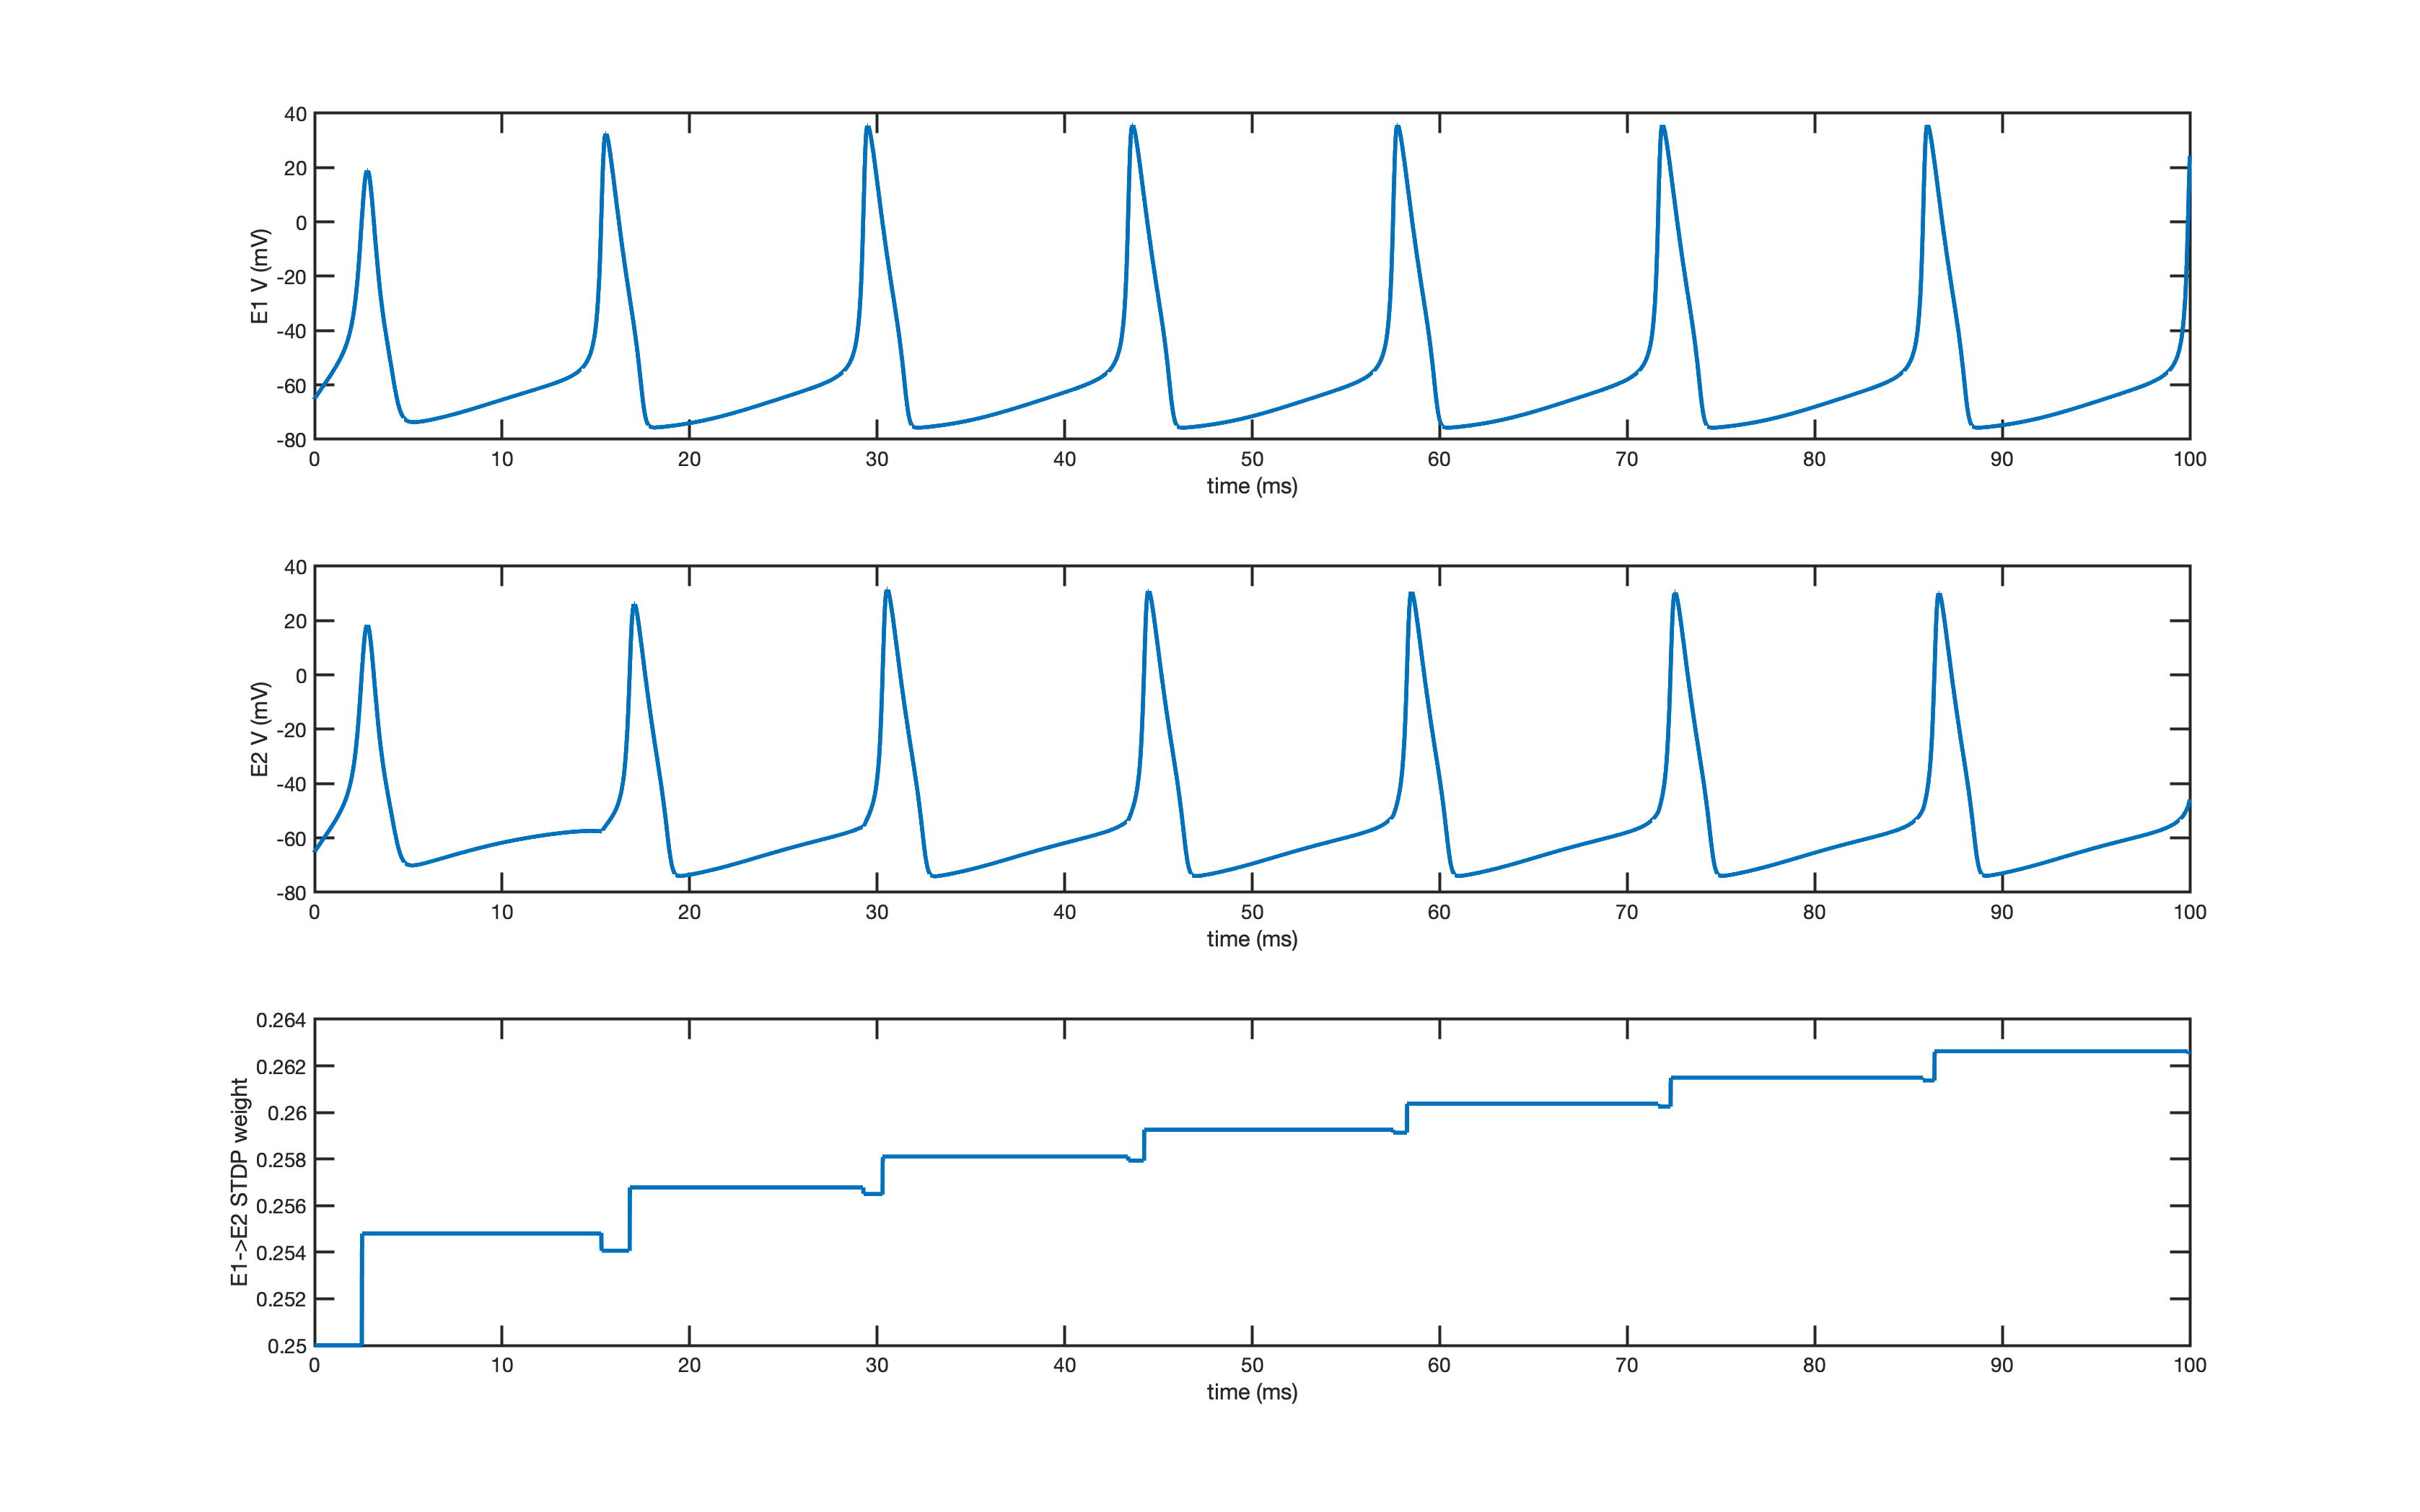


% Define neuron equations
eqns = {
    'dV/dt= I + @current; V(0)=-65' % define voltage dynamics and initial conditions
    '{iNa,iK}'                      % add Na+ and K+ mechanisms to neuron (i.e., insert INa and IK into @current)
    'I=10'                          % set tonic drive parameter
    'monitor V.spikes(0)'           % monitor spikes
    };
% Define network with two neurons connected by plastic synapse
spec = [];
spec.populations(1).name = 'E1';
spec.populations(1).equations = eqns;
spec.populations(2).name = 'E2';
spec.populations(2).equations = eqns;
spec.connections(1).direction = 'E1->E2';         % add synapse from E1 to E2
spec.connections(1).mechanism_list = 'STDP_Isyn'; % use built-in STDP mechanism

% Simulate model
data = dsSimulate(spec,'tspan',[0 100]);

% Plot changes in synaptic weights
figure('units','normalized','position',[0 0 1 1])
subplot(3,1,1); plot(data.time, data.E1_V); % E1 voltage dynamics (spiking)
xlabel('time (ms)'); ylabel('E1 V (mV)');
subplot(3,1,2); plot(data.time, data.E2_V); % E2 voltage dynamics (spiking)
xlabel('time (ms)'); ylabel('E2 V (mV)');
subplot(3,1,3); plot(data.time, data.E2_E1_STDP_Isyn_w); % weight changes
xlabel('time (ms)'); ylabel('E1->E2 STDP weight');